#                        Blind Source Separation

##                                            HW6-Section-3

                 Mohammadreza Arani         :::::::::::::         810100511

                                                           1402/02/20   

clear; clc; close all;

## Part-1:

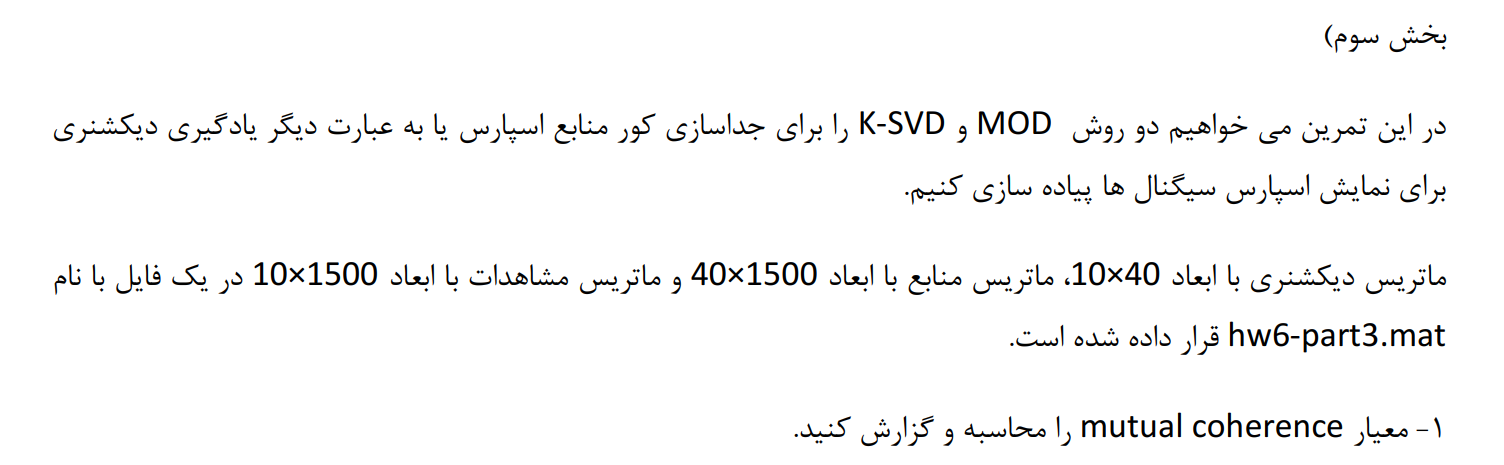


Data_Q3  = load("hw6-part3.mat");
D_Part_1 = Data_Q3.D;
% Calculation of MU based on implemented function in previous Section:
[MU_out, MU_Index_Out] = MU_Calc_Mine(D_Part_1);
disp("Mutual Coherence is : "+ MU_out);

Mutual Coherence is : 0.86803


disp(" Maximum Coherence happens for column "+MU_Index_Out(1)+" and column "+MU_Index_Out(2))

 Maximum Coherence happens for column 13 and column 38


## Part-2:

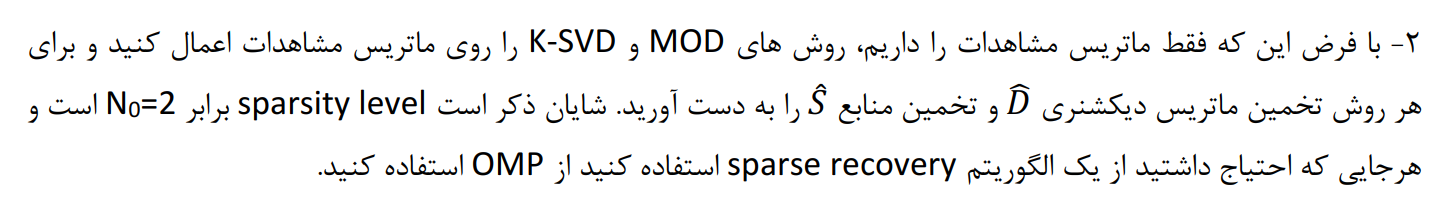

## MOD

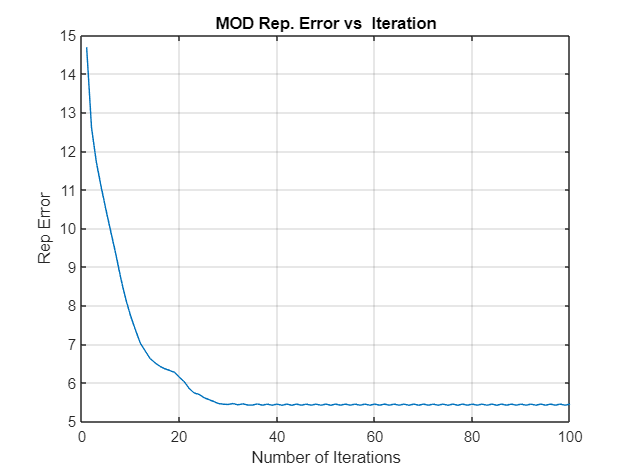


X_part_1   = Data_Q3.X;
S_part_1   = Data_Q3.S;
N0_Part_1  = Data_Q3.N0;

S_X_p1 = size(X_part_1);
S_S_p1 = size(S_part_1);

D_hat_MOD = randn(S_X_p1(1) , S_S_p1(1)) ; 
D_hat_MOD = D_hat_MOD ./ sqrt(sum(D_hat_MOD.^2,1)); 

T = S_S_p1(2);
S_hat_MOD = randn(S_S_p1);

IterMax = 100;
MSE_MOD = zeros(1,IterMax);
Rep_MOD = MSE_MOD;
MOD_delta_Time = MSE_MOD;


for i=1:IterMax
    tic;
    % First Step of Alternation Minimization:
    for t=1:T
        S_hat_MOD(:,t) = OMP_Mine_CAlc( X_part_1(:,t)  , D_hat_MOD , N0_Part_1);
    end
    % Second Step of Alternation Minimization:
    D_hat_MOD = X_part_1*pinv(S_hat_MOD);                % Second Step of Altrnation Minimization
    D_hat_MOD = D_hat_MOD ./ sqrt(sum(abs(D_hat_MOD).^2));  % Normalize Each Column of D
    % Calculate the MSE:
    MSE_MOD(i) = mse(X_part_1 , D_hat_MOD*S_hat_MOD);
    Rep_MOD(i) = norm(X_part_1 - D_hat_MOD*S_hat_MOD,"fro");
    MOD_delta_Time(i) = toc;
end

figure()
plot(Rep_MOD)
grid on
xlabel("Number of Iterations")
ylabel("Rep Error")
title("MOD Rep. Error vs  Iteration")

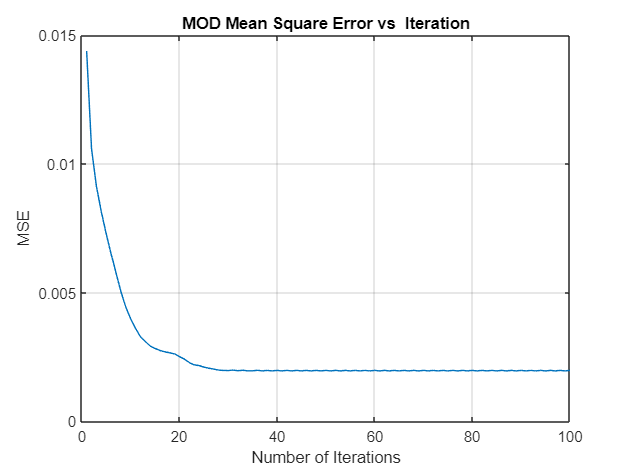

figure()
plot(MSE_MOD)
grid on
xlabel("Number of Iterations")
ylabel("MSE")
title("MOD Mean Square Error vs  Iteration")

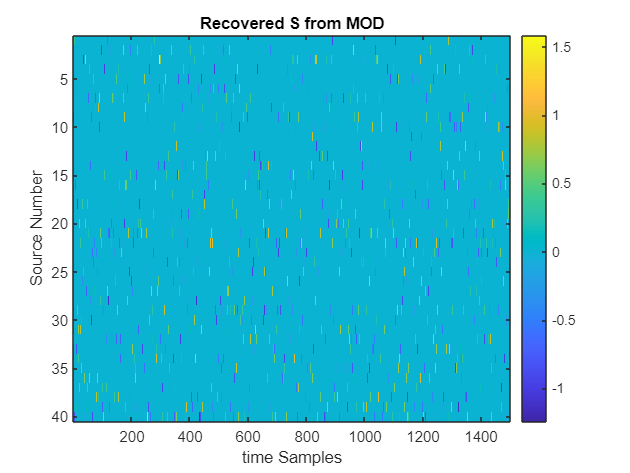





figure()
imagesc(S_hat_MOD)
title("Recovered S from MOD")
xlabel("time Samples")
ylabel("Source Number")
colorbar

## K-SVD:

D_hat_K_SVD = randn(S_X_p1(1) , S_S_p1(1)) ;
T = S_S_p1(2);
S_hat_K_SVD = randn(S_S_p1);

IterMax = 100;
MSE_K_SVD = zeros(1,IterMax);
Rep_K_SVD = MSE_K_SVD;
K_SVD_delta_Time = MSE_K_SVD;


for i=1:IterMax
    tic;
    % First Step of Alternation Minimization:
    for t=1:T
        S_hat_K_SVD(:,t) = OMP_Mine_CAlc( X_part_1(:,t)  , D_hat_K_SVD , N0_Part_1);
    end
    % Second Step of Alternation Minimization:
    for n=1:S_S_p1(1)

        % Choose corresponding Index:
        D_ind_SVD = 1:S_S_p1(1);
        D_ind_SVD(n) = [];

        % Calculate the Residual X:
        X_res = X_part_1 - D_hat_K_SVD(:, D_ind_SVD)*S_hat_K_SVD(D_ind_SVD,:) ;
        [U,S,V] = svd(X_res);

        % Sort:
        [S_sorted, idx] = sort(diag(S), 'descend');

        % Reorder the columns of U and rows of V based on the sorted indices
        U_sorted = U(:, idx);
        V_sorted = V(:, idx);

        % Assign U and V to D and S:
        D_hat_K_SVD(:,n) = U_sorted(:,1);
        Zer0Index = find(abs(S_hat_K_SVD(n,:))<1e-6);
        S_hat_K_SVD(n,:) = S_sorted(1)*V_sorted(:,1);
        S_hat_K_SVD(n,Zer0Index) = 0;
    end
    % Calculate the MSE
    MSE_K_SVD(i) = mse(X_part_1 , D_hat_K_SVD*S_hat_K_SVD);
    Rep_K_SVD(i) = norm(X_part_1 - D_hat_K_SVD*S_hat_K_SVD,"fro" );
    K_SVD_delta_Time(i) = toc;
end



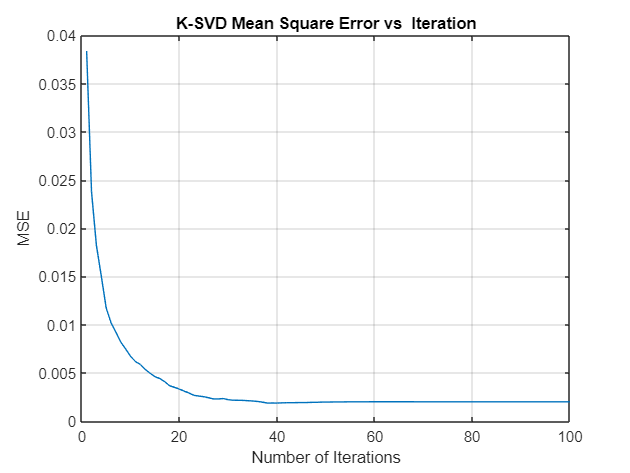

figure()
plot(MSE_K_SVD)
grid on
xlabel("Number of Iterations")
ylabel("MSE")
title("K-SVD Mean Square Error vs  Iteration")

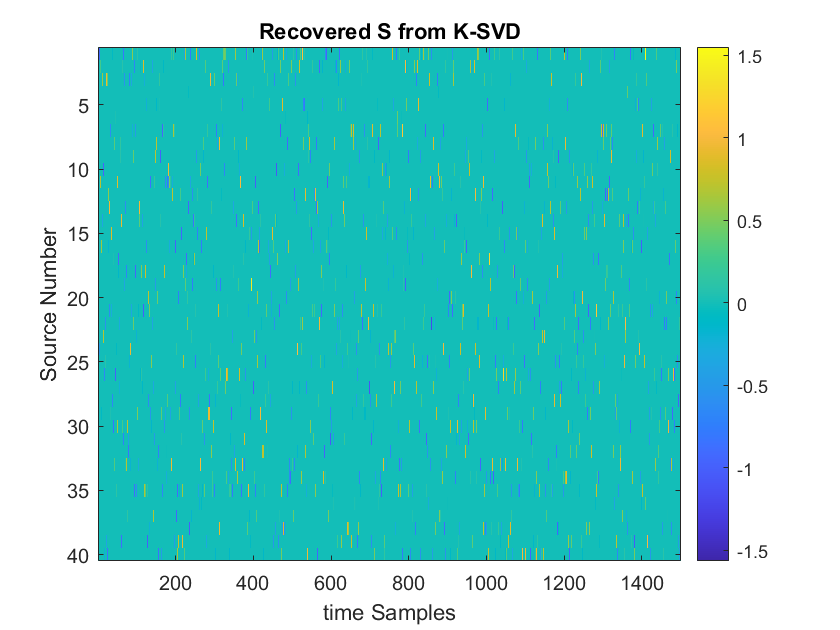



figure()
imagesc(S_hat_K_SVD)
title("Recovered S from K-SVD")
xlabel("time Samples")
ylabel("Source Number")
colorbar

## Comparison of MOD and K-SVD

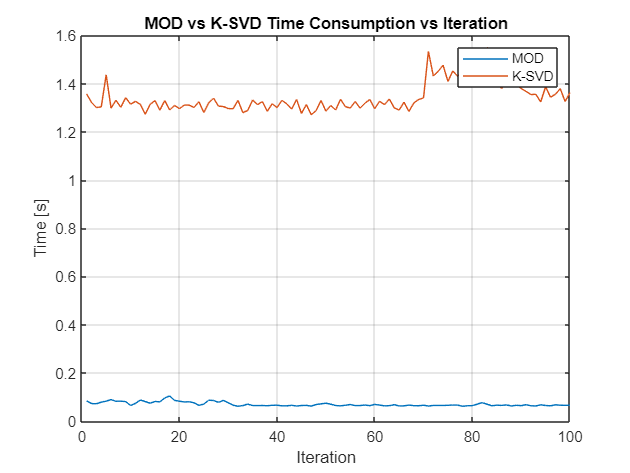

figure()
plot(MOD_delta_Time)
hold on
plot(K_SVD_delta_Time)
title("MOD vs K-SVD Time Consumption vs Iteration")
grid on
xlabel("Iteration")
ylabel("Time [s]")
legend("MOD", "K-SVD")
hold off

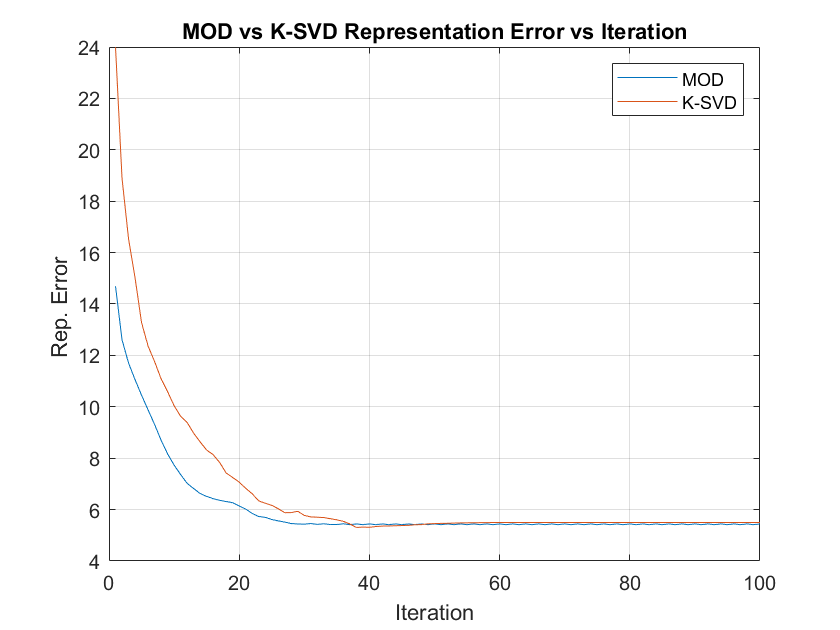


figure()
plot(Rep_MOD)
hold on
plot(Rep_K_SVD)
hold off
title("MOD vs K-SVD Representation Error vs Iteration")
grid on
xlabel("Iteration")
ylabel("Rep. Error ")
legend("MOD", "K-SVD")

## Part-5:

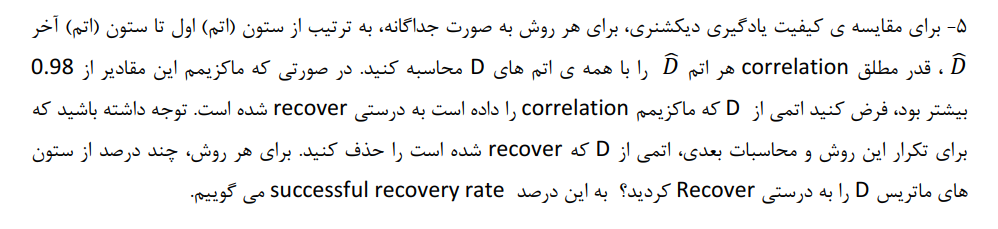

%  [index_remove_Recovered_SVD,counter_SVD] = Recovery_Calc_D(D_hat_K_SVD , D_Part_1 )
[D_hat_K_SVD,Succ_Rec_Num_K_SVD] = Recovery_Calc_D(D_hat_K_SVD , D_Part_1 )

D_hat_K_SVD =     0.1782    0.0616    0.0067    0.1625    0.3639    0.4327    0.0122    0.1649    0.0618    0.4058    0.2026    0.1501    0.0474    0.0566    0.0335    0.4449    0.2526    0.2153    0.1193    0.2008    0.5785    0.1953    0.0616    0.4537    0.5148    0.2438    0.1673    0.3889    0.4332    0.0122    0.4850    0.1253    0.2074    0.2967    0.0104    0.7846    0.5423    0.5423   -0.1961    0.0474
   -0.6215   -0.1760   -0.3174    0.0084   -0.2324   -0.1279   -0.4431    0.0825   -0.1913   -0.2467   -0.0544   -0.6273    0.3462   -0.0874    0.0277   -0.1406    0.1289    0.1900    0.0406   -0.6426   -0.2063    0.0911   -0.1760    0.0279   -0.2644   -0.4059    0.4084   -0.3795    0.1706   -0.4431   -0.1181   -0.0341   -0.4491    0.1849   -0.7348   -0.0020    0.0024    0.0024    0.4371    0.3462
    0.2242   -0.0384   -0.3175    0.2171   -0.3800    0.1295    0.3095    0.3399    0.0991    0.0853    0.2795   -0.5091   -0.2191    0.1899    0.3371   -0.3047    0.5043   -0.0618   -

Succ_Rec_Num_K_SVD = 35


disp(Succ_Rec_Num_K_SVD/size(D_Part_1,2)*100+" % of the Columns of D where recovered successfully!")

87.5 % of the Columns of D where recovered successfully!


[D_hat_MOD,Succ_Rec_Num_MOD] = Recovery_Calc_D(D_hat_MOD , D_Part_1 )

D_hat_MOD =    -0.1758   -0.0923    0.0390    0.2260   -0.3966   -0.4335    0.3994   -0.1268    0.0271   -0.4379   -0.1994   -0.1633   -0.4335    0.0519   -0.0337   -0.4501    0.2579   -0.2236   -0.0721   -0.2179   -0.5771   -0.2257    0.1714   -0.4354   -0.2257    0.2496    0.1537    0.3766    0.4346   -0.3966   -0.4963    0.1982   -0.2001   -0.2942    0.1537    0.8094   -0.5369   -0.2236    0.3994   -0.0512
    0.6312    0.2277   -0.3149    0.1461    0.2639    0.1159    0.3185   -0.0980   -0.1995    0.2276    0.0289    0.6023    0.1159   -0.0766   -0.0389    0.1557    0.1005   -0.1757   -0.0292    0.6506    0.1909   -0.1176    0.1419   -0.0063   -0.1176   -0.3909    0.4169   -0.3897    0.1618    0.2639    0.1519   -0.0313    0.4689   -0.2153    0.4169   -0.0473    0.0039   -0.1757    0.3185   -0.3375
   -0.2250   -0.0150   -0.3193    0.1594    0.3539   -0.1148   -0.1668   -0.3396    0.0387   -0.0702   -0.2264    0.5560   -0.1148    0.1628   -0.3139    0.2835    0.5122    0.0572    0.

Succ_Rec_Num_MOD = 34


% [index_remove_Recovered_MOD,counter_MOD] = Recovery_Calc_D(D_hat_MOD, D_Part_1 )


disp(Succ_Rec_Num_MOD/size(D_Part_1,2)*100+" % of the Columns of D where recovered successfully!")

85 % of the Columns of D where recovered successfully!


## Part-6:

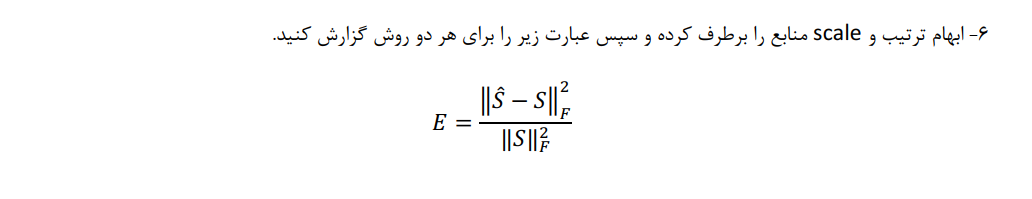

S_hat_K_SVD_OMP = S_hat_K_SVD;
S_hat_MOD_OMP = S_hat_MOD;
for t=1:T
    S_hat_K_SVD_OMP(:,t) = OMP_Mine_CAlc( X_part_1(:,t)  , D_hat_K_SVD , N0_Part_1);
    S_hat_MOD_OMP(:,t) = OMP_Mine_CAlc( X_part_1(:,t)  , D_hat_MOD , N0_Part_1);
end
[Erroes_S_Hat_K_SVD,S_Hat_Chosen_K_SVD]  = Perm_AMP_Disamb(S_hat_K_SVD_OMP,S_part_1);

disp("Error of S_K_SVD equals to: "+ min(Erroes_S_Hat_K_SVD));

Error of S_K_SVD equals to: 1.4798


[Erroes_S_Hat_MOD,S_Hat_Chosen_MOD]  = Perm_AMP_Disamb(S_hat_MOD_OMP,S_part_1);
disp("Error of S_MOD equals to: "+ min(Erroes_S_Hat_MOD));

Error of S_MOD equals to: 1.8142


function [Erroes_B,B_Hat_Chosen]  = Perm_AMP_Disamb(B_Hat,S_Amp) %% Perm_AMP_Disamb
Perm_1 = B_Hat;
Perm_2 = -B_Hat;
Perm_3 = B_Hat([end, 1:end-1],:);
Perm_4 = -B_Hat([end, 1:end-1],:);
Perms = { Perm_1,Perm_2,Perm_3,Perm_4  };
% Estimate S:
S_hat_1 = Perm_1;
S_hat_1_Normalised = S_hat_1/norm(S_hat_1,'fro');
S_hat_2 = Perm_2;
S_hat_2_Normalised = S_hat_2/norm(S_hat_2,'fro');
S_hat_3 = Perm_3;
S_hat_3_Normalised = S_hat_3/norm(S_hat_3,'fro');
S_hat_4 = Perm_4;
S_hat_4_Normalised = S_hat_4/norm(S_hat_4,'fro');
% Calc Error:
S_Amp_Normalized = S_Amp/norm(S_Amp,'fro');

Error_1 = (norm((S_hat_1_Normalised)-(S_Amp_Normalized),'fro'))^2/norm((S_Amp_Normalized),"fro")^2 ; 
Error_2 = (norm((S_hat_2_Normalised)-(S_Amp_Normalized),'fro'))^2/norm((S_Amp_Normalized),"fro")^2 ; 
Error_3 = (norm((S_hat_3_Normalised)-(S_Amp_Normalized),'fro'))^2/norm((S_Amp_Normalized),"fro")^2 ; 
Error_4 = (norm((S_hat_4_Normalised)-(S_Amp_Normalized),'fro'))^2/norm((S_Amp_Normalized),"fro")^2 ; 

Erroes_B = [Error_1,Error_2,Error_3,Error_4];
[ ~, index] = min(Erroes_B);
B_Hat_Chosen = Perms{index};
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function  [D_Hat_sorted,Counter] = Recovery_Calc_D(D_hat , D )
%index_remove_Recovered

% D_hat = D_KSVD;
D_Hat_sorted = D_hat;
Counter = 0;
for i=1:size(D,2)
    for j = 1 : size(D_hat,2)
        if(abs(D(:,i)'*D_hat(:,j)) > 0.98)
            Counter = Counter + 1;
            D_Hat_sorted(:,i) = D_hat(:,j);
            D_hat(:,j)=[];
            break;    
        end
    end
end


%     [~ , Col_D] = size(D_hat);
%     Temp_D_check = D;
% 
%     index_remove_Recovered =[];
%     counter = 0;
%     for i=1:Col_D
%         Cor_Col_D =  D_hat(:,i)'*Temp_D_check ;
%         %max(abs(Cor_Col_D))
%         if(max(abs(Cor_Col_D)) > 0.98) % Check to see whether we have recovered this column or not
%             [~ , index_remove_Recovered(counter+1)] = max(Cor_Col_D);
%             Temp_D_check(index_remove_Recovered) = [];
%             counter = counter+1;
%         end
%      
%     end

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [MU_out, MU_Index_Out] = MU_Calc_Mine(D)

Temp     = (ones(size(D'*D)) - eye(size(D'*D))).* abs( D'*D );
[MU_Vals , MU_Index] =  max(Temp)  ;
[MU_out , MU_Index2]  = max(MU_Vals);

MU_Index_Out = [MU_Index2 , MU_Index(MU_Index2)];
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function  s_OMP = OMP_Mine_CAlc( x  , D , N0)

    xr = x;
    Dr = D;
    idx_OMP = zeros(1, N0);
    for i = 1 : N0
        [~, idx_OMP(i)] = max(abs(xr'*Dr),[],'omitnan');
        xr = xr - x'*Dr(:, idx_OMP(i))*Dr(:,idx_OMP(i));
        if i > 1
            xr = xr - D(:,idx_OMP(1:i))*(pinv(D(:,idx_OMP(1:i)))*xr);
        end
        Dr(:,idx_OMP(i)) = nan;
    end

    s_OMP = zeros(size(D, 2), 1);
    s_OMP(idx_OMP) = pinv(D(:, idx_OMP))*x;



    % 
    % xr = X;
    % [~ , Col_D] = size(D);
    % Chosen_IDX = inf+zeros(1,Col_D);
    % S_hat = zeros(Col_D,1); 
    % for  i=1:N0
    %     
    %     B = D;
    % 
    %     if(i>1)
    %         B(:,Chosen_IDX(1:i-1)) = []; % Removing previously chosen Indices!
    %     end
    % 
    %     Corr_matrix = abs(repmat(xr,1,Col_D-i+1).*B);
    %     Corr_sum = sum(Corr_matrix,1); % Summation for each Column -->> a Row Vector
    %     [Value,Idx] = max(Corr_sum); % Choosing Best Fitted
    % 
    %     if(sum(Idx>Chosen_IDX)>0)
    %         Idx  = Idx + sum(Idx>Chosen_IDX) ; % Update the Index with respect to the Original D 
    %     end
    % 
    %     Chosen_IDX(i) =  Idx;
    %     xr = xr - X'*D(:,Idx)*D(:,Idx); % xr = x  - <x,di>di
    % 
    %     % Update Coefficients:
    %     if(i>1)
    %         D_sub_omp = D(:,Chosen_IDX(1:i)) ;
    %         xr = xr - D(:,Chosen_IDX(1:i))*(pinv(D_sub_omp)*xr);
    %     end
    %     % Stop Criteria:
    % %     if(norm(x - D(:,Chosen_IDX_3(1:i)) ,2)<thresh )
    % %         break;
    % %     end
    %     S_hat(Chosen_IDX(i)) = pinv(D(:,i))*X;
    % end

% delta_t_OMP = toc;
% disp("Elapsed Time (OMP): "+ delta_t_OMP+"(s)");
end
